# IMAGE PROCESSING OF DEWETTING FROM VIDEO 

Takes a ".avi" video file, creates a plot of normalized area vs time. Saves an "_Area.txt" file that stores the analyzed data and can be passed into the "dataprocessing" file for further processing and analysis.

% NOTE: this program requires Matlab "image processing toolbox" to run on Matlab 2020a

% Last tested: August 2020
% Version: Matlab 2020a                     

% August, 2020
% Modified by Vincent Xia

## Clear everything

clear variables global;
close all hidden;
clc;
warning('off','all'); %Suppress warnings for faster exec.

## Input dialogs

Analysis settings:

[file,path] = uigetfile('*.avi'); %choose .avi file (can change format if needed)

analysis_settings = inputdlg({'Remove objects smaller than X pixels 100-1000', ...
                                'Skip Frames [1-1000]',...
                                'Initial frame above surface',...
                                'Select video frame for area analysis'},'Sample',...
                                [1 50; 1 20;1 20;1 20],{'250','3','40','2500'});
    
    fname = strcat(path,file); % gets file name from uigetfile

% remove objects smaller than X = will not designate a few pixels as wet/dry (reduces noise)

% Skip frames = # of frames skipped between analysis (smaller file)

% Initial frame above surface = first frame where dome is exposed (doesn't
% count previous frames as part of the time)

% Plot video: Change to 1 for getting a video of the plot; else keep 0 to speed up execution.

% Video frame for area analysis: Background frame for defining total area; pick frame 
                                 % after edge 'gravity-driven' dewetting occurs, and once
                                 % interference patterns begin

Analysis types:

                                 
analysis_type = inputdlg({'New or old software?(1=New,0=Old)',...
                          'Lubricin or Water?(1=lubricin, 0=water)',...
                          'Circle or freehand area fit? (1=circle, 0=freehand)'},...
                          'Analysis Type', [1 40; 1 40; 1 40], {'1','1','1'});

% New or old software: Old uEye Cockpit laptop software or New Thorcam software from 2/25/2020 onwards
% Water or lubricin: Which are you measuring dewetting on?
% Circle/freehand: the area selection method for the selected area_frame
                                 

Video output types:

video_output_types = inputdlg({ 'Falsecolor final output? (1=no, 0=yes) ',...
                          'Output analyzed frames?(1=no, 0=yes)',...
                          'Output individual masks video?(1=no, 0=yes)',...
                          'Output black/white mask?(1=no,0=yes)',...
                          'Output animated plot? (1=no, 0=yes)'},...
                          'Output video types (note: choosing yes on any of these will be slower)', [1 40; 1 40; 1 40; 1 40; 1 40], {'1','1','1','1','1'});

% Falsecolor ouput: makes a falsecolor overlay of the binary mask on the original frame                       
% Output analyzed frames: makes a copy of the analyzed frames from the original video
% Output individual masks: makes a montage copy of the individual masks for debugging purposes

## Parameters for image processing

Initialize our parameters from the dialog boxes:

[remove_Pixels,skip_frame,t_0,area_frame,bg,...
    sftwre_type,liquid_type,area_fit_type,...
    output_false_color,output_analyzed_frames,output_all_masks,output_black_white_mask,output_animated_plot] = fill_params(analysis_settings,analysis_type,video_output_types); %fill in all the parameters from the dialog boxes using helper function


Theshold values for hue, saturation, value analysis (use Threshold Check or Matlab "Color Thresholder" App to test values)


if sftwre_type == 0  %Old uEye Cockpit software
    if liquid_type == 1 %DI water
        % Used "DIWater HPL3 RT2" file from 2-21-2020, frame 1000 to obtain
        % threshold values  
        hueThresholdLow = 0;
        hueThresholdHigh = 1;
        saturationThresholdLow = 0;
        saturationThresholdHigh = 1;
        valueThresholdLow = 0.7;
        valueThresholdHigh = 1;   
    elseif liquid_type == 0 %lubricin    
        %Used ".5 ugml lubricin DS HPL 2 37C 1" from 1-20-2020,frame 2085
        %to obtain threshold values
        hueThresholdLow = .4;
        hueThresholdHigh = .5;
        saturationThresholdLow = .3;
        saturationThresholdHigh = .4;
        valueThresholdLow = 0.7;
        valueThresholdHigh = 1;
    end
elseif sftwre_type == 1 %New Thorcam software
    if liquid_type == 0 %DI Water

        % From 07-05-20 HPL3 DIWater Test 2 file
        hueThresholdLow = 0;
        hueThresholdHigh = 1;
        saturationThresholdLow = 0;
        saturationThresholdHigh = 1;
        valueThresholdLow = 0.659;
        valueThresholdHigh = 1;
        
    elseif liquid_type == 1 %lubricin
        
        
  %      For 08-12-20 1 ugmL HPL3 RT solvent trap
%         hueThresholdLow = .438;
%         hueThresholdHigh = .535;
%         saturationThresholdLow = .177;
%         saturationThresholdHigh = .236;
%         valueThresholdLow = .718;
%         valueThresholdHigh = .906;

        
    % For 07-19-20 .5 ugmL HPL1 NR (less discriminatory)
%         hueThresholdLow = .410;
%         hueThresholdHigh = .554;
%         saturationThresholdLow = .104;
%         saturationThresholdHigh = .271;
%         valueThresholdLow = .439;
%         valueThresholdHigh = .780;
        
        
        % For 10-13-20 1 ugmL lubricin TS HPL4 37C
        hueThresholdLow = .422;
        hueThresholdHigh = .500;
        saturationThresholdLow = .104; %.164 <--- saturation boundaries have a substantial impact on video thresholding!
        saturationThresholdHigh = .271; %.233
        valueThresholdLow = .490; %.490
        valueThresholdHigh = .761; %.761
        

    end 
end

## Video Import

video=VideoReader(fname); %starts reading video
fname=fname(1:end-4); %removes .avi or other file extension from filename
nframes=video.NumFrames; % gets # of frames in video
input_fps=video.FrameRate; % gets frames/second in initial video
vidHeight = video.Height; %gets video height
vidWidth = video.Width; %gets video width
background_frame = read(video, bg); %gets background frame in video (used for deleting background)

## Crop and convert background

background=imcrop(rgb2gray(background_frame),[0,0,1024,768]); % Background frame is when dome crosses interface, converts to grayscale

## Define output video parameters; open videos for writing

output_framerate = 20; %output frame rate
outputVideo=VideoWriter(strcat(fname,'_maskVideo'),'MPEG-4'); %writes black/white video showing wet area (black) vs. dry area (white)
outputVideo.FrameRate = output_framerate; %sets output video frame rate

analyzedVideo = VideoWriter(strcat(fname,'_analyzedOrigVideo'),'MPEG-4'); %writes video showing the original frames that were analyzed
analyzedVideo.FrameRate = output_framerate; %sets output video frame rate

falseColorVideo = VideoWriter(strcat(fname,'_falseColor'),'MPEG-4'); %writes falsecolor video showing wet area (green) and analyzed dry area (red)
falseColorVideo.FrameRate = output_framerate; %sets output video frame rate

allMasksVideo = VideoWriter(strcat(fname,'_allMasks'),'MPEG-4'); %writes video showing the original frames that were analyzed
allMasksVideo.FrameRate = output_framerate; %sets output video frame rate


## Set total area

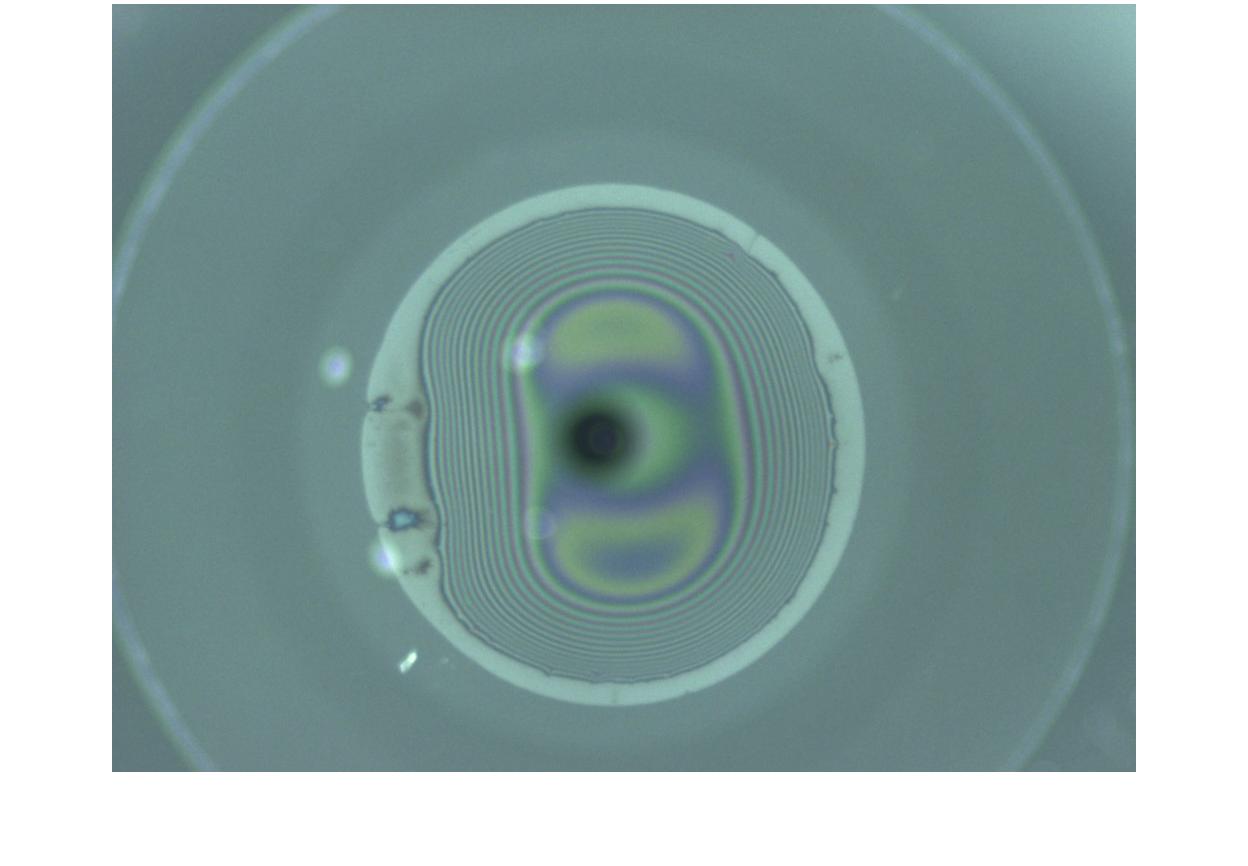

totalareaframe        = read(video,area_frame);                    % Read user specified frame for area analysis
totalareaframecropped = imcrop(totalareaframe,[0,0,1024,768]);     % Crop last frame
totalareaframegray    = rgb2gray(totalareaframecropped);           % Grayscale last frame

[mask, max_area, shadowMask, cameraarea, totalAreaCenter, totalAreaRadius] = userdraw_ROI(totalareaframecropped,area_fit_type); %helper function to handle our ROI drawing

## Analyze video

wait_bar = waitbar(0,'Analyzing... Go grab a cup of coffee...');
open(outputVideo); % opens output video for writing
if (output_analyzed_frames == 0) 
    open(analyzedVideo); % opens video for analyzed frames from original video
end
if (output_all_masks == 0)
    open(allMasksVideo); % opens video for displaying individual masks
end
if (output_false_color == 0)
    open(falseColorVideo); % opens false color overlay video
end

grain_areas = zeros(1,(floor((nframes-1)/skip_frame)*skip_frame + 1)); % initialize grain_areas
vid_time = zeros(1,(floor((nframes-1)/skip_frame)*skip_frame + 1));  % initialize vid_time tag for output videos
graph_time = zeros(1,(floor((nframes-1)/skip_frame)*skip_frame + 1));  % initialize graph_time tag for output videos

for frame=t_0:skip_frame:3000
    waitbar(frame/nframes,wait_bar); % update wait bar to show analysis progress
    orig_frame=read(video,frame); % reading individual frames from input video
    crop_frame=imcrop(orig_frame,[0,0,1024,768]); 
    gray_frame=rgb2gray(crop_frame); % grayscale frame from video
    subtract_frame=gray_frame - background; % Subtract background frame from current frame

### Masking and binarization: 


%     if (frame > area_frame) %adjust this depending on how much noise your analysis picks up at the beginning. starting this later will lead to less noise
        subtract_frame(shadowMask) = 0; %clear every subtract_frame pixel inside the shadowMask | applies the camera mask
        subtract_frame(~mask) = 0; %apply area mask
        bw_frame_mask=imbinarize(subtract_frame);
%     else
%         bw_frame=imbinarize(subtract_frame); % "Blanket" method to suppress noise before area frame
%         bw_frame_mask = bw_frame.*mask; % Add mask of overall circle specified from UI input
%     end
    
     

Area mask

 
    bw_frame_mask_clean = bwareaopen(bw_frame_mask, remove_Pixels); % remove connected objects that are smaller than 250 pixels in size
    bw_frame_mask_clean = ~bwareaopen(~bw_frame_mask_clean, remove_Pixels); % remove holes that are smaller than 20 pixels in size
    

HSV Masking

    hsv_frame=rgb2hsv(crop_frame); % convert to hsv image
    hsv_frame(shadowMask) = 0; % apply camera mask
    hsv_frame(~mask) = 0; % apply area mask
    
    % Apply each color band's particular thresholds to the color band
	hueMask = (hsv_frame(:,:,1) >= hueThresholdLow) & (hsv_frame(:,:,1) <= hueThresholdHigh); %makes mask of the hue image within theshold values
	saturationMask = (hsv_frame(:,:,2) >= saturationThresholdLow) & (hsv_frame(:,:,2) <= saturationThresholdHigh); %makes mask of the saturation image within theshold values
	valueMask = (hsv_frame(:,:,3) >= valueThresholdLow) & (hsv_frame(:,:,3) <= valueThresholdHigh); %makes mask of the value image within theshold values
    
    HSV_mask = hueMask & saturationMask & valueMask; % defines area that fits within hue mask, saturation mask, and value mask    
    
    % Fill in the holes of the mask 
	HSV_mask_rmv_maskHoles = ~bwareaopen(~HSV_mask, remove_Pixels);
    
    % Filter out small objects.
    HSV_mask_rmv_obj = bwareaopen(HSV_mask_rmv_maskHoles, remove_Pixels); %fill in holes smaller than 250 pixels in size
    
    % apply binarization mask
    HSV_bw_mask = HSV_mask_rmv_obj & bw_frame_mask_clean;


Count Area; use** Edge Algorithm 2 **to throw away inside regions

 
    [finalMask,grain_areas(frame)] = countArea(HSV_bw_mask,totalAreaRadius,gray_frame,totalAreaCenter);      
    

Write final videos  

    if(frame>t_0) %Only write video after dome has crossed the interface (bg frame)
        
        finalMask = im2uint8(finalMask~=0);
        Norm_area = 1-(grain_areas./(max_area-cameraarea)); % normalize dry area based on  total area minus camera shadow area. subtract from 1 to get wet area            
        vid_time(frame)=(frame)*(1/input_fps); % raw video time
        graph_time(frame)=(frame-t_0)*(1/input_fps); %adjusts time for skipped frames and initial frame rate  
        
        writeOutputVideos(output_false_color,output_analyzed_frames,output_all_masks,output_black_white_mask,...
                          gray_frame,crop_frame,orig_frame,HSV_mask,HSV_mask_rmv_obj,bw_frame_mask_clean,finalMask,...
                          outputVideo,falseColorVideo,analyzedVideo,allMasksVideo, ...
                          graph_time,vid_time,Norm_area,frame)

    end
end

close(outputVideo); %close output videowriter
close(analyzedVideo); %close analyzed frames video
close(allMasksVideo); %close individual masks video
close(falseColorVideo); %close falsecolor video
close(wait_bar); %closes wait bar

## Plot Dewetted Area

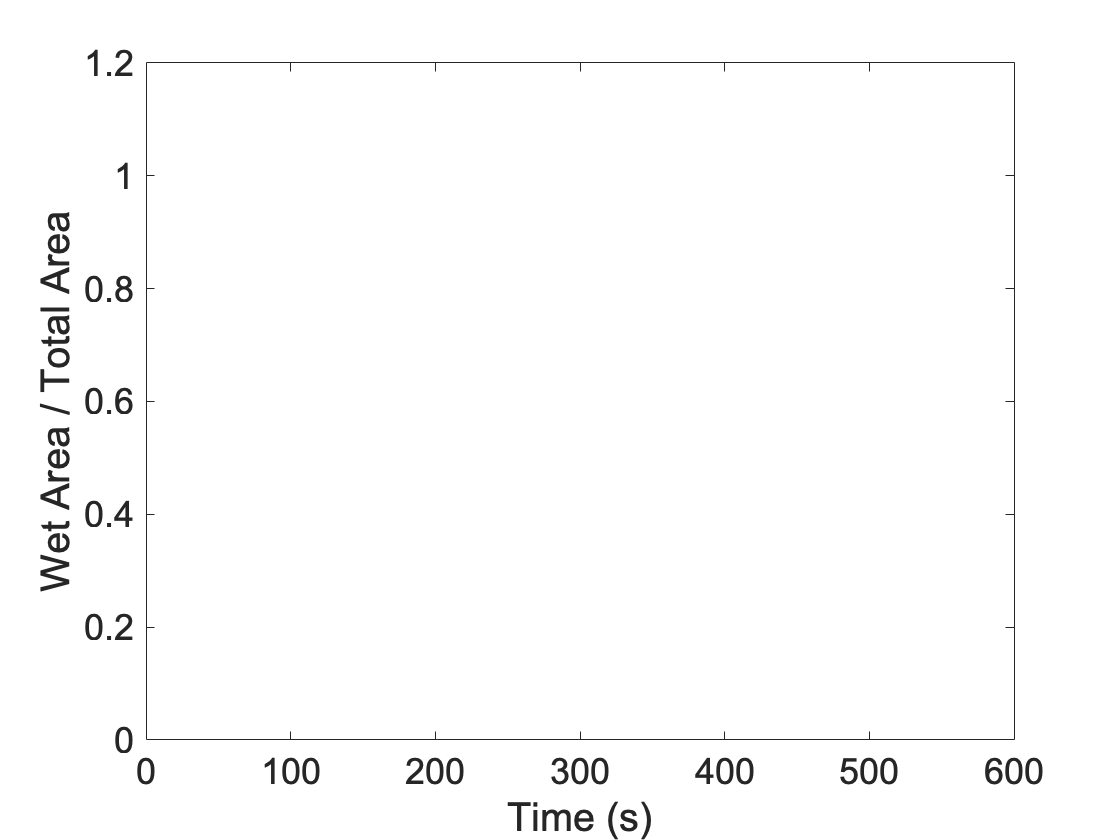

%Re-normalize area 
Norm_area=1-(grain_areas./(max_area-cameraarea));
%Create time array;
% time = zeros(1,(floor((nframes-1)/skip_frame)*skip_frame + 1));   %initialize time
time = zeros(1,length(Norm_area)); % initialize time
for frame=t_0:skip_frame:nframes
    time(frame)=(frame)*(1/input_fps); %adjusts time for skipped frames and initial frame rate
end

% Figure formatting
figure, hold on 
xlim([0 600]);
ylim([0 1.2]);
xlabel('Time (s)','FontSize' , 28,'FontName'   , 'Arial')
ylabel('Wet Area / Total Area','FontSize' , 20,'FontName'   , 'Arial')
set(gca,'FontName', 'Arial','FontSize',18);
set(gcf, 'PaperPositionMode', 'auto');
box on;


dewet_data_size = floor((nframes-1)/skip_frame + 1);
dewet_data = zeros(dewet_data_size, 2);
j0 = 0;

for frame = 1:skip_frame:nframes
    j0 = j0 + 1;
    dewet_data(j0,:) = [time(frame), Norm_area(frame)];
end

if(~output_animated_plot) % plots video of animated plot
    outputAnimatedPlot(nframes,skip_frame,time,Norm_area,fname);
end


## Generate preview plot

plot(time,Norm_area,'o');

Error using plot
Vectors must be the same length.

print('-dtiff',strcat(fname,'_graph.tiff'));

## Store analyzed data into text file to be used with image processing code

time=time';
Norm_area=Norm_area';
fid=fopen(strcat(fname,'_Area.txt'),'w');
fprintf(fid, '%d %d \n', [dewet_data]');
fclose(fid);

## Store all data (including skipped frames) into text file

fid=fopen(strcat(fname,'_alldata.txt'),'w');
fprintf(fid, '%d %d \n', [time Norm_area]');
fclose(fid);

## Store image processing parameters into text file

fid=fopen(strcat(fname,'_Parameters.txt'),'w'); %saves parameters used in file for analysis 
fprintf(fid, 'remove_Pixels = %d \n', remove_Pixels);
fprintf(fid, 't_0 = %d \n', t_0);
fprintf(fid, 'bg = %d \n', bg);
fprintf(fid, 'frame for area analysis = %d \n', area_frame);
fprintf(fid, 'frames_skipped = %d \n', skip_frame);
fprintf(fid, 'HueThreshold = (%.3f,%.3f) \n', hueThresholdLow, hueThresholdHigh);
fprintf(fid, 'SaturationThreshold = (%.3f,%.3f) \n', saturationThresholdLow, saturationThresholdHigh);
fprintf(fid, 'ValueThreshold = (%.3f,%.3f)', valueThresholdLow, valueThresholdHigh);
fclose(fid);

## Switch warnings on back again

warning('on','all');

# Helper functions

Initialize parameters from dialog boxes:

function [remove_Pixels,skip_frame,t_0,area_frame,bg,...
            sftwre_type,liquid_type,areaFitType,...
            output_false_color,output_analyzed_frames,output_all_masks,output_black_white_mask,output_animated_plot] = fill_params(input_dialog,analysis_type,video_output_types)

    remove_Pixels = str2double(input_dialog{1}); % parameter passed to 'bwareaopen' that tells us how small (in pixels) objects need to be before we remove them from the analysis
    skip_frame = str2double(input_dialog{2}); %frequency with which we analyze video frames
    t_0=str2double(input_dialog{3});  % intial time when the dome reaches its maximum height
    area_frame=str2double(input_dialog{4}); % Background frame for defining total area; pick frame 
                                            % after edge 'gravity-driven' dewetting occurs, and once
                                            % interference patterns begin
                                                                                  
    bg = t_0+5; % Keep at t_0 for videos with fast dewetting
    
    sftwre_type = str2double(analysis_type{1}); % from analysis_type input dialog
    liquid_type = str2double(analysis_type{2}); % from analysis_type input dialog
    areaFitType = str2double(analysis_type{3}); %use an assisted freehand on the area_frame fitting, or just use a circle

    output_false_color = str2double(video_output_types{1}); % print the final binary mask output video in BW or falsecolor overlay on original frame
    output_analyzed_frames = str2double(video_output_types{2}); % tells us whether or not to print an mp4 of analyzed frames from original video
    output_all_masks = str2double(video_output_types{3}); % tells us whether or not to print an mp4 of individual masks from video
    output_black_white_mask = str2double(video_output_types{4}); % simple black/white mask mp4 video
    output_animated_plot=str2double(video_output_types{5}); % should we plot the animated video or not?
    
end

Highest level helper function to allow user to draw the ROI

function [mask, max_area, shadowMask, cameraarea, center, radius] = userdraw_ROI(totalareaframecropped,areaFitType)
    %set the total area mask
    roi = showAreaROI(totalareaframecropped,areaFitType); %show the frame and return an roi that we can calculate things from
    if (areaFitType == 1)
        center = roi.Center;
        radius = roi.Radius;
    else 
        mask = createMask(roi);
        stats = regionprops('table',mask,'Centroid','MajorAxisLength','MinorAxisLength'); % estimate the center and radius for the drawn region
            center = stats.Centroid;
            diameter = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
            radius = diameter/2;
    end
    mask = createMask(roi);
    max_area = nnz(mask);     
    

    %set the camera shadow area
    shadowROI = showShadowROI(totalareaframecropped);    
    shadowMask = createMask(shadowROI);
    cameraarea = nnz(shadowMask); 
    
    close;
end

Mid-level helper function to show the freehand or circle ROI

function [roi] = showAreaROI(totalareaframecropped,areaFitType)
    imshow(totalareaframecropped);                                 % Show area frame as total area input
    
    if (areaFitType == 1)
        xlabel('Draw circle around total area, adjust as needed, then double click when done!','FontSize',16,'FontName','Arial');
        roi = drawcircle('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");
    else
        xlabel('Draw freehand around total area; double-click to close and double-click again to finish','FontSize',16,'FontName','Arial');
        roi = drawassisted('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");
        while (isempty(roi.Position)) % repeat if the user deletes the ROI
            roi = drawassisted('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");
        end
    end
    customWait(roi); % wait for double click
end

function [shadowROI] = showShadowROI(totalareaframecropped)
    imshow(totalareaframecropped);                                 % Show area frame as total area input
    xlabel('Draw circle around camera shadow, adjust as needed, then double click when done!','FontSize',16,'FontName','Arial');
    shadowROI = drawcircle('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");

    customWait(shadowROI);
end

Use a custom wait function to block the MATLAB command line while you interact with the rectangle. This example specifies a function called `customWait` (defined at the end of the example). While the command line is blocked, resize and reposition the rectangle so that it encompasses one pear. Double-click on the circle to resume execution of the `customWait` function. This is the custom wait function that blocks the program execution when you click an ROI. When you have finished interacting with the ROI, the function returns the position of the ROI. 

function customWait(hROI) %general wait function
    % Listen for mouse clicks on the ROI
    l = addlistener(hROI,'ROIClicked',@clickCallback);
    
    % Block program execution
    uiwait;
    
    % Remove listener
    delete(l);
end


This click callback function resumes program execution when you double-click the ROI. Note that event data is passed to the callback function as an [`images.roi.ROIClickedEventData`](docid:images_ref.mw_81029a52-9470-4901-a436-7fd4180ba6a7) object, which enables you to define callback functions that respond to different types of actions. For example, you could define a callback function to resume program execution when you click the ROI while pressing the Shift key or when you click a specific part of the ROI such as the label.

function clickCallback(~,evt)
    if strcmp(evt.SelectionType,'double')
        uiresume;
    end
end

Circle specific custom wait function

function [center, radius] = customWaitCircle(hROI)
    l = addlistener(hROI,'ROIClicked',@clickCallback);  % Listen for mouse clicks on the ROI
    
    uiwait; % Block program execution
    
    % Remove listener
    delete(l);
    
    % Return the circle's center and radius
    center = hROI.Center;
    radius = hROI.Radius;
end

### Count area 

calculate the dewetted area array using the provided mask and 'edge algorithm 2'

function [labelImg, area] = countArea(coloredObjectsMask,totalAreaRadius,gray_frame,totalAreaCenter)

    connComp = bwconncomp(coloredObjectsMask,8); % finds connected components within binary image (connectivity of 4)                
    [nrow,ncol] = size(connComp.PixelIdxList);
    
    radiusRmv = totalAreaRadius - 10; % radius for our clearing region. The center lies at the center of our 'totalArea' circle
                
    for idx = 1:ncol % for each component in connComp
        [row,col] = ind2sub(size(gray_frame), connComp.PixelIdxList{1,idx});
        coord = cat(2,col,row);
        
        loc = (coord(:,1) - totalAreaCenter(1)).^2 + (coord(:,2) - totalAreaCenter(2)).^2;
                   
        if ~any(loc > radiusRmv^2) % if any pixels in the connected component fall outside our clearing region, with radius 'radiusRmv'...   
            coloredObjectsMask(connComp.PixelIdxList{1,idx}) = 0; % if the component falls entirely inside our clearing region, set pixels to 0 (black)
        end                                  
    end
    
    connCompClean = bwconncomp(coloredObjectsMask); % finds connected components again, since now we've removed objects in our clearing region
    labelImg = labelmatrix(connCompClean); % creates labeled matrix from bwconncomp structure
    
    graindata = regionprops(connCompClean, 'Area'); % computes 'Area' measurement of connCompClean
    
    area = sum([graindata.Area]); % sum of areas in our cleaned connected components to be used when calculating wet vs dry area   
    %return area
    

end


**Write videos**

outputs the videos based on analysis and user custom input param's

function writeOutputVideos(outputFalseColor,outputAnalyze,outputMasks,output_black_white_mask,...
                              gray_frame,crop_frame,orig_frame,HSV_mask,HSV_mask_rmv_obj,bw_frame_mask_clean,finalMask, ...
                              outputVideo,falseColorVideo,analyzedVideo,allMasksVideo, ...
                              graphTime,vidTime,Norm_area,i)

        frameNum = sprintf('Frame: %d | Video time: %.3f sec | Graph time: %.3f sec | Area: %.3f', i, vidTime(i), graphTime(i), Norm_area(i)); % prints frame #, time stamp, and area for each mp4 frame


Output black & white mask video:

        if (~output_black_white_mask) %comment out to print black and white mask video                   
            
            FinalImg_insert = insertText(finalMask,[100 50],frameNum,'AnchorPoint','LeftBottom'); % requires Matlab Computer Vision Toolbox            
            writeVideo(outputVideo,FinalImg_insert); % writes video with analyzed frames  
        end

Output falsecolor:        

        if (~outputFalseColor)  % make a falsecolor overlay of our final mask over the original grayscale image 
            FinalImgFuse = imfuse(finalMask,gray_frame,'falsecolor','Scaling','joint','ColorChannels',[1 2 0]); %create falsecolor overlay of binary mask over original image    
            falseColorInfo = sprintf('red = binary mask | green = original img | yellow = both'); % prints false color info                
            FinalImg_insert = insertText(FinalImgFuse,[100 50],frameNum,'AnchorPoint','LeftBottom','BoxColor',{'black'},"TextColor",{"white"}); % note: requires Matlab Computer Vision Toolbox
            FinalImg_insert = insertText(FinalImg_insert,[100 100],falseColorInfo,'AnchorPoint','LeftBottom','BoxColor',{'black'},"TextColor",{"white"}); % note: requires Matlab Computer Vision Toolbox    
            writeVideo(falseColorVideo,FinalImg_insert); %writes video with analyzed frames
        end        

Output analyzed frames:

        if (~outputAnalyze) 
            frameNum = sprintf('Frame: %d | Time: %.3f sec ', i , graphTime(i)); % prints frame #, time stamp, and area for each mp4 frame
            image = insertText(orig_frame,[30 725],frameNum,'FontSize',55,'BoxColor','white','AnchorPoint','LeftBottom'); %requires Matlab Computer Vision Toolbox
            writeVideo(analyzedVideo,image);
        end

Output individual masks:       

        if(outputMasks == 0) 
            box_color = {"green"};
           
            im0 = insertText(crop_frame,[100 50],"orig image",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            im1 = insertText(im2uint8(HSV_mask),[100 50],"HSV mask",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
                fuse = imfuse(im2uint8(HSV_mask),im2uint8(bw_frame_mask_clean),'falsecolor','Scaling','joint','ColorChannels',[1 2 0]); %create falsecolor overlay of area mask with HSV mask
            im2 = insertText(fuse, [100 50],'HSV w/ binarize overlay','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            im3 = insertText(im2uint8(bw_frame_mask_clean),[100 50],"Binarize mask (contains area mask)",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');            
            im6 = insertText(finalMask,[100 50],'final mask','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            
            im7 = insertText(im2uint8(HSV_mask_rmv_obj),[100 50],"HSV mask after removing small objects and small mask holes",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            
            
            
            blank = zeros(size(im0));
            concat1 = cat(1,im0,im1,im2); %concatenate the images together
            concat2 = cat(1,im3,im6,im7);
            concatFinal = cat(2,concat1,concat2);
            
            finalImage = insertText(concatFinal,[300 50],frameNum,'FontSize',20,'AnchorPoint','LeftBottom'); %requires Matlab Computer Vision Toolbox
            writeVideo(allMasksVideo,finalImage);
        end     
end

        

Output animated plot video:

function outputAnimatedPlot(nframes,skip_frame,time,Norm_area,fname)
    %Plot video settings
    hold on;
    output_framerate=40;
    outputVideo=VideoWriter(strcat(fname,'_plot'),'MPEG-4');
    outputVideo.FrameRate = output_framerate;
    open(outputVideo);
    
    plot_movie = repmat(struct(getframe(gcf)),1,floor((nframes-1)/skip_frame)*skip_frame + 1); %initialize plot_movie
    for i=1:skip_frame:nframes
        plot(time(i),Norm_area(i),'o')
        plot_movie(i)=getframe(gcf);
        writeVideo(outputVideo,plot_movie(1,i));
    end
    close(outputVideo);
    
end

